% Clearing workspace and loading data
clearvars;
close all; % Close all open figures

% Load the datasets and priors
load('TrainingSamplesDCT_8_new.mat');
D_FG = TrainsampleDCT_FG;
D_BG = TrainsampleDCT_BG;

% Read and preprocess the image
I = imread('cheetah.bmp');
gt_mask = imread('cheetah_mask.bmp');
gt_mask = im2double(gt_mask);
img = im2double(I);

% Defining patch size
patch_size = 8;

% Adding zero-padding to the original image
img_size = size(img);
padded_size = img_size + [patch_size-1, patch_size-1];
padded_img = zeros(padded_size);
padded_img(4:img_size(1)+3, 5:img_size(2)+4) = img;

% Updating image size after padding
[rows, cols] = size(padded_img);

% Initializing a matrix to store flattened vectors
num_patches = (rows - patch_size + 1) * (cols - patch_size + 1);
X_feature = zeros(num_patches, 64);

% Setting order 
order = [0   1   5   6  14  15  27  28;
         2   4   7  13  16  26  29  42;
         3   8  12  17  25  30  41  43;
         9  11  18  24  31  40  44  53;
         10  19  23  32  39  45  52  54;
         20  22  33  38  46  51  55  60;
         21  34  37  47  50  56  59  61;
         35  36  48  49  57  58  62  63];

% Adjusting indices by adding 1
order = order + 1;

index = 1;

% Sliding the 8x8 grid and performing DCT
for i = 1:rows - patch_size + 1
    for j = 1:cols - patch_size + 1
        % Extracting the 8x8 patch
        patch = padded_img(i:i+patch_size-1, j:j+patch_size-1);
        
        % Computing the 2D DCT of the patch
        dct_patch = dct2(patch);
        
        for k = 1:8
            for l = 1:8
                % Arranging according to the ZigZag Pattern txt file
                X_feature(index, order(k, l)) = dct_patch(k, l);
            end
        end
        index = index + 1;
    end
end

% Define parameters for EM
maxIter = 2000;  % Maximum number of iterations for EM
tol = 1e-4;     % Tolerance for convergence check

% Define the number of dimensions to test
dimensions = [1, 2, 4, 8, 16, 24, 32, 40, 48, 56, 64];
numMixtures = 1;  % Number of GMM mixtures for each class
components = 32;   % Number of Gaussian components in each mixture

% Initialize the error matrix
errors = zeros(length(dimensions), numMixtures^2);

for dIdx = 1:length(dimensions)
    d = dimensions(dIdx);
    
    % Select the first d features from the zig-zag pattern
    X_feature_d = X_feature(:, 1:d);
    
    for fgMix = 1:numMixtures
        for bgMix = 1:numMixtures
            fprintf('Foreground Mixture %d, Background Mixture %d, Dimensions: %d\n', fgMix, bgMix, d);
            
            % Before the loop over components
            epsilon = 1e-3;  % Small number to prevent variances from going to zero
            
            % EMAlgorithm, include epsilon:
            [mu_FG, Sigma_FG, pi_FG, ~] = EMAlgorithm(D_FG(:, 1:d), components, maxIter, tol, epsilon);
            [mu_BG, Sigma_BG, pi_BG, ~] = EMAlgorithm(D_BG(:, 1:d), components, maxIter, tol, epsilon);
            
            % Classify the image using the trained GMM
            classifiedImage = classifyWithGMM(X_feature_d, mu_FG, Sigma_FG, pi_FG, mu_BG, Sigma_BG, pi_BG, gt_mask);
            
            % Calculate error probability
            errorIdx = (fgMix - 1) * numMixtures + bgMix;
            errors(dIdx, errorIdx) = computeError(classifiedImage, gt_mask);
            
            % Uncomment the following lines if you want to display the classified image
            % figure;
            % imshow(classifiedImage, 'Colormap', [0 0 0; 1 1 1]);
            % title(sprintf('Cheetah Mask, F_g = %d, B_g = %d', fgMix, bgMix));
        end
    end
end

Foreground Mixture 1, Background Mixture 1, Dimensions: 1
Foreground Mixture 1, Background Mixture 1, Dimensions: 2
Foreground Mixture 1, Background Mixture 1, Dimensions: 4
Foreground Mixture 1, Background Mixture 1, Dimensions: 8
Foreground Mixture 1, Background Mixture 1, Dimensions: 16


Convergence reached after 760 iterations.


Foreground Mixture 1, Background Mixture 1, Dimensions: 24


Convergence reached after 635 iterations.


Foreground Mixture 1, Background Mixture 1, Dimensions: 32


Convergence reached after 42 iterations.


Convergence reached after 894 iterations.


Foreground Mixture 1, Background Mixture 1, Dimensions: 40


Convergence reached after 40 iterations.


Convergence reached after 613 iterations.


Foreground Mixture 1, Background Mixture 1, Dimensions: 48


Convergence reached after 81 iterations.


Convergence reached after 475 iterations.


Foreground Mixture 1, Background Mixture 1, Dimensions: 56


Convergence reached after 40 iterations.


Convergence reached after 1033 iterations.


Foreground Mixture 1, Background Mixture 1, Dimensions: 64


Convergence reached after 147 iterations.


Convergence reached after 881 iterations.


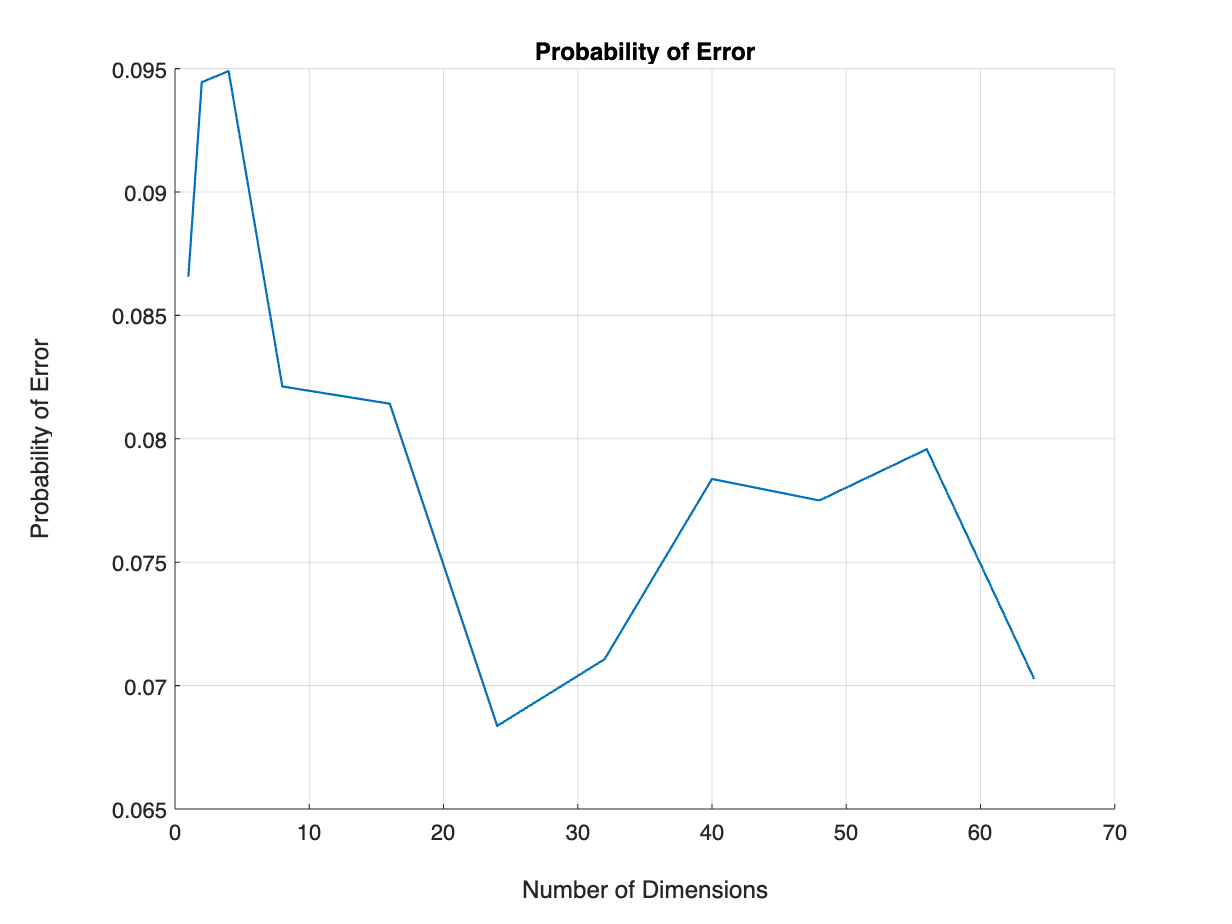

% Plot the error probabilities as a function of the number of dimensions
for fgMix = 1:numMixtures
    figure;
    hold on; % Hold on to the current figure to plot multiple lines
    lowerBound = 0;
    upperBound = 0.14;
    for bgMix = 1:numMixtures
        mixIdx = (fgMix - 1) * numMixtures + bgMix;
        filterederrors = errors(errors >= lowerBound & errors <= upperBound);
        plot(dimensions, errors(:, mixIdx), 'LineWidth', 1, 'DisplayName', sprintf('B_g = %d', bgMix));
    end
    
    hold off; % Release the hold after plotting all lines
    
    xlabel('Number of Dimensions');
    ylabel('Probability of Error');
    title(sprintf('Probability of Error'));
    grid on;
    %legend; % Add a legend to distinguish between different background mixtures
end

function [mu, Sigma, pi] = initializeGMMParameters(X, K, epsilon)
    [N, D] = size(X); % N is the number of data points, D is the number of dimensions
    mu = zeros(K, D);
    Sigma = zeros(D, D, K);
    pi = ones(1, K) * (1/K); % Initialize mixing coefficients to uniform values
    
    % Initialize means to random data points
    mu = X(randperm(N, K), :);
    % % Initialize the diagonal of each covariance matrix randomly, ensuring non-zero with epsilon
    % Sigma_values = (0.1 + epsilon) * rand(1, D); % Adjust 0.1 based on your needs
    % Sigma_d = repmat(Sigma_values, K, 1);
    % 
    % % Fill the diagonal of each covariance matrix
    for k = 1:K
        Sigma(:, :, k) = eye(D,D);
    end
end

function h = EStep(X, mu, Sigma, pi)
    K = size(mu, 1);
    N = size(X, 1);
    h = zeros(N, K);
    
    for j = 1:K
        h(:, j) = pi(j) * mvnpdf(X, mu(j, :), Sigma(:, :, j));
    end
    
    h = h ./ sum(h, 2); % Normalize responsibilities
end

function [mu, Sigma, pi] = MStep(X, h, epsilon)
    K = size(h, 2);
    D = size(X, 2);
    Nk = sum(h, 1);
    mu = (h' * X) ./ Nk'; % Vectorized mean update
    Sigma = zeros(D, D, K);
    
    for j = 1:K
        X_centered = X - mu(j, :);
        Sigma_j = sum((X_centered.^2) .* h(:, j), 1) / Nk(j);
        Sigma(:, :, j) = diag(max(Sigma_j, epsilon)); % Ensure diagonal variances
    end
    
    pi = Nk / sum(Nk); % Vectorized mixing coefficients update
end

function [mu, Sigma, pi, logLikelihood] = EMAlgorithm(X, K, maxIter, tol, epsilon)
    % Initialize the GMM parameters
    [mu, Sigma, pi] = initializeGMMParameters(X, K, epsilon);
    logLikelihood = -inf;  % Initialize log-likelihood
    N = size(X, 1);  % Number of data points
    
    for iter = 1:maxIter
        % E-step
        h = EStep(X, mu, Sigma, pi);
        
        % Compute log-likelihood for convergence check
        logLikelihoods = zeros(N, 1);

        for j = 1:K
            logLikelihoods = logLikelihoods + log(pi(j)) + log(mvnpdf(X, mu(j, :), Sigma(:, :, j)));
        end
        
        newLogLikelihood = sum(logLikelihoods);
        
        % Check for convergence
        if abs(newLogLikelihood - logLikelihood) < tol
            fprintf('Convergence reached after %d iterations.\n', iter);
            break;
        end
        
        logLikelihood = newLogLikelihood;
        
        % M-step
        [mu, Sigma, pi] = MStep(X, h, epsilon);
    end
end

function error = computeError(classifiedImage, gt_mask)
    error = min(sum(abs(classifiedImage - gt_mask), 'all') / numel(gt_mask),0.2);
end

% Function Definitions
function classifiedImage = classifyWithGMM(X_feature, mu_FG, Sigma_FG, pi_FG, mu_BG, Sigma_BG, pi_BG, gt_mask)
    % Classify dataå based on trained GMM parameters
    % X_feature: data points to classify
    % mu_FG, Sigma_FG, pi_FG: GMM parameters for the foreground
    % mu_BG, Sigma_BG, pi_BG: GMM parameters for the background
    N = size(X_feature, 1); % Number of data points
    likelihood_FG = zeros(N, 1);
    likelihood_BG = zeros(N, 1);
    
    % Compute likelihood for each point under the foreground GMM
    for j = 1:size(mu_FG, 1)
        likelihood_FG = likelihood_FG + pi_FG(j) * mvnpdf(X_feature, mu_FG(j, :), Sigma_FG(:, :, j));
    end
    
    % Compute likelihood for each point under the background GMM
    for j = 1:size(mu_BG, 1)
        likelihood_BG = likelihood_BG + pi_BG(j) * mvnpdf(X_feature, mu_BG(j, :), Sigma_BG(:, :, j));
    end
    
    % Classify based on which likelihood is higher
    classifiedImageVector = double(likelihood_FG > likelihood_BG);
    classifiedImage = reshape(classifiedImageVector, size(gt_mask, 2), size(gt_mask, 1))';
end
